# **AASI HW1**

Po-Tao, Lin

B11501037

Date: 2025/09/18

clear; close all; clc;

## Problem 1

### Part 1 Data setting function

rng(3);  % fix random seed (convinience to regenerate)

function [x,y,z,mean_vals,std_vals] = randn3d(Mx,My,Mz, sx,sy,sz,N)
    x = Mx + sx*randn(N,1);
    y = My + sy*randn(N,1);
    z = Mz + sz*randn(N,1);

    %% (b) Compute mean and std
    mean_vals = [mean(x), mean(y), mean(z)];    % mean value
    std_vals  = [std(x), std(y), std(z)];       % standard deviation

    figure('Position',[100,100,600,400]);
    set(gcf,'Color','White')
    if  N==30
        scatter3(x,y,z,'k','filled','DisplayName','Random Point','AlphaVariable',0.5);
    else
        scatter3(x,y,z,0.3*log((20)),'k','filled','DisplayName','Random Point','AlphaVariable',0.5);
    end

    xlabel('X'); ylabel('Y'); zlabel('Z');
    title([sprintf('%d',N), ' Random Points in 3D']);
    grid on; axis tight manual;
    
    
    
    %% (c) Mark 1σ range
    hold on;
    plot3([mean(x)-std(x), mean(x)+std(x)], [mean(y), mean(y)], [mean(z), mean(z)], 'r-', 'LineWidth',2,'DisplayName',['s_x = ',sprintf('%.3f',std(x))]);
    plot3([mean(x), mean(x)], [mean(y)-std(y), mean(y)+std(y)], [mean(z), mean(z)], 'g-', 'LineWidth',2,'DisplayName',['s_y = ',sprintf('%.3f',std(y))]);
    plot3([mean(x), mean(x)], [mean(y), mean(y)], [mean(z)-std(z), mean(z)+std(z)], 'b-', 'LineWidth',2,'DisplayName',['s_z = ',sprintf('%.3f',std(z))]);
    fprintf('%.3f,%.3f,%.3f',std(x),std(y),std(z))
    legend('Location','northwest')
    exportgraphics(gca,['P1point',sprintf('%d',N),'.pdf'])
end


### Part 2 Main procedure - Interface

0.143,0.232,0.103

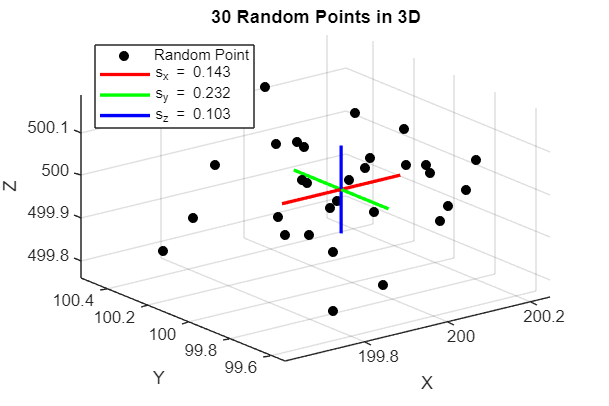

0.199,0.302,0.102

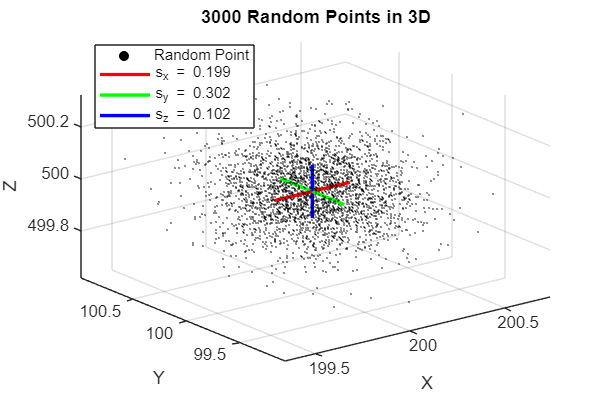

0.201,0.300,0.100

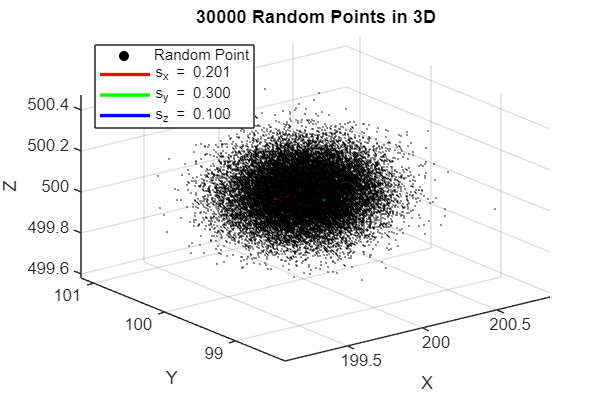

0.200,0.300,0.100

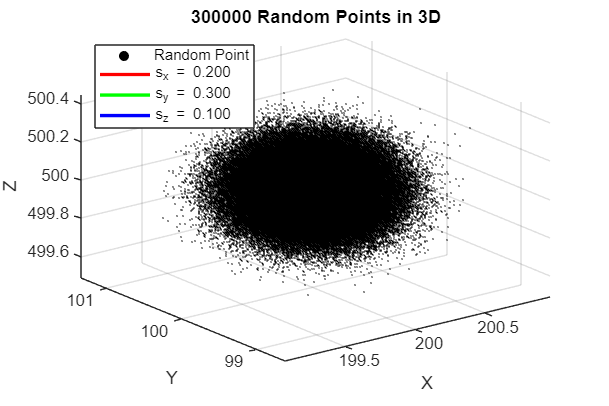

0.200,0.300,0.100

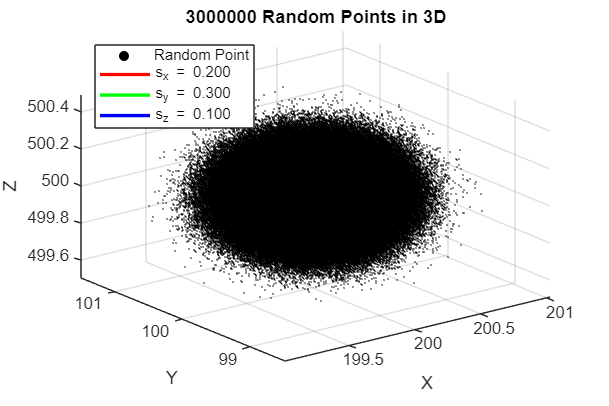

MEANset = zeros(5,3);STDset = zeros(5,3);
Nset = [30,3000,30000,300000,3000000];
for i = 1:5
    
    [~,~,~,MEANset(i,:),STDset(i,:)] =  randn3d(200,100,500,0.2,0.3,0.1,Nset(i));
end

### Part 3 Plot sample data

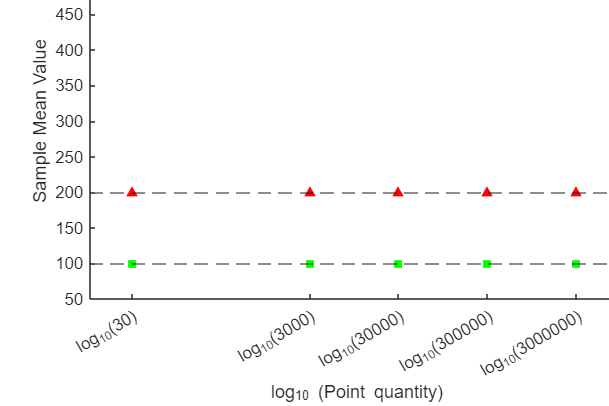

figure('Position',[100,100,600,400])
set(gcf,'Color','White')
scatter(log10(Nset), MEANset(:,1), 'r^','filled');
hold on 
scatter(log10(Nset), MEANset(:,2), 'gs','filled');
scatter(log10(Nset), MEANset(:,3), 'bO','filled');
xticks(log10(Nset));                        
xticklabels(compose('log_{10}(%d)', Nset)); 
xlabel('log_{10} (Point quantity)');ylabel('Sample Mean Value')
yline([200,100,500],'--')
legend('$\bar{x}$','$\bar{y}$','$\bar{z}$','location','eastoutside','Interpreter','latex','Fontsize',12)
exportgraphics(gca,'P1relationMEAN.pdf')



figure('Position',[100,100,600,400])
set(gcf,'Color','White')
scatter(log10(Nset), STDset(:,1), 'r^','filled');
hold on 
scatter(log10(Nset), STDset(:,2), 'gs','filled');
scatter(log10(Nset), STDset(:,3), 'bO','filled');
xticks(log10(Nset));                        
xticklabels(compose('log_{10}(%d)', Nset)); 
xlabel('log_{10} (Point quantity)');ylabel('Sample Standard Deviation')
yline([0.2,0.3,0.1],'--')
legend('$s_x$','$s_y$','$s_z$','location','eastoutside','Interpreter','latex','Fontsize',12)
exportgraphics(gca,'P1relationSTD.pdf')

## Problem 3

clear; close all; clc;

### Part 1: generate network 

rng(3);  % fix random seed (convinience to regenerate)

nPts = 13;
coords = 400*rand(nPts,2);      % XY-location [m]
elev   = 20 + 5*randn(nPts,1);  % elevation [m]

% network (13 points, 4 loops)
edges = [1 8; 8 7; 7 3; 3 12; 12 10; 10 1;  % loop 1: [1 8 7 3 12 10]
        1 6; 6 4; 4 11; 11 8;               % loop 2: [1 6 4 11 8]
        11 9; 9 13; 13 12;                  % loop 3
        13 2; 2 5; 5 6;];                   % loop 4            

nEdges = size(edges,1);

### Part 2 true level difference

true_dh = elev(edges(:,2)) - elev(edges(:,1));

### Part 3 add random error (7mm/sqrt(km))

dist_km = sqrt(sum((coords(edges(:,2),:) - coords(edges(:,1),:)).^2,2))/1000; % distance [km]
sigma = 0.007.* sqrt(dist_km); %7mm/sqrt(km)
rand_err = sigma .* randn(nEdges,1);

meas_dh = true_dh + rand_err;

### Part 4 true error

true_err = sigma .* randn(nEdges,1); % generate an true error

### Part 5 ouput ASCII

BS_Pt = edges(:,1);
FS_Pt = edges(:,2); 

% sufficient digits (3)
fmt1 = '%.3f'; % 3 digit right '.' , save to [mm]
fmt2 = '%.2e'; % 2 digit science record (1 is left to the '.')
T_out = table( ...
    BS_Pt, ...
    FS_Pt, ...
    arrayfun(@(x) sprintf(fmt1, x), true_dh, 'UniformOutput', false), ...
    arrayfun(@(x) sprintf(fmt1, x), meas_dh, 'UniformOutput', false), ...
    arrayfun(@(x) sprintf(fmt2, x), true_err, 'UniformOutput', false), ...
    'VariableNames', {'BS_Pt','FS_Pt','dh_true','dh_meas','terror'} ...
);
disp(T_out)

    BS_Pt    FS_Pt      dh_true        dh_meas         terror    
    _____    _____    ___________    ___________    _____________

      1        8      {'6.880'  }    {'6.878'  }    {'-9.30e-04'}
      8        7      {'4.089'  }    {'4.088'  }    {'1.14e-03' }
      7        3      {'-11.006'}    {'-11.007'}    {'1.58e-03' }
      3       12      {'3.314'  }    {'3.312'  }    {'1.53e-03' }
     12       10      {'-6.784' }    {'-6.785' }    {'6.63e-04' }
     10        1      {'3.508'  }    {'3.507'  }    {'-1.14e-03'}
      1        6      {'4.287'  }    {'4.290'  }    {'1.33e-03' }
      6        4      {'-0.226' }    {'-0.225' }    {'-1.53e-03'}
      4       11      {'1.349'  }    {'1.346'  }    {'1.02e-03' }
     11        8      {'1.470'  }    {'1.469'  }    {'-1.13e-03'}
     11        9      {'-4.976' }    

writetable(T_out,'level_network_results.txt','Delimiter','\t','QuoteStrings',false)

### Part 6 Configuration

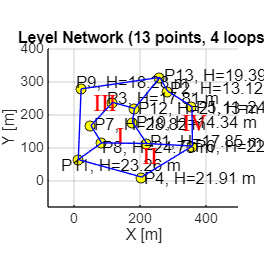

labels = arrayfun(@(i) sprintf('P%d, H=%.2f m', i, elev(i)), ...
                  1:nPts, 'UniformOutput', false);
figure('Position',[100 100 700 700]); 
set(gcf,'color','white')
hold on; grid on; axis equal
plot(coords(:,1), coords(:,2), 'ko','MarkerFaceColor','y')
textshiftx = 4*[2,2,-4,2,3,2,2,0,-4,3,-13,3,3];
textshifty = 4*[2,2,3,-1,0,0,1,-3,5,0,-4,0,2];
text(coords(:,1)+textshiftx(:), coords(:,2)+textshifty(:), labels,'FontSize',10)
text(120,130,'$\mathrm{I}$','Color','r','Interpreter','latex','FontSize',14)
text(200,70,'$\mathrm{II}$','Color','r','Interpreter','latex','FontSize',14)
text(50,230,'$\mathrm{III}$','Color','r','Interpreter','latex','FontSize',14)
text(320,170,'$\mathrm{IV}$','Color','r','Interpreter','latex','FontSize',14)

for i=1:nEdges %edge
    plot(coords(edges(i,:),1), coords(edges(i,:),2), 'b-')
end

xlim([-80,500]); ylim([-80,400]);
title('Level Network (13 points, 4 loops)')
xlabel('X [m]'); ylabel('Y [m]')
exportgraphics(gca,'P3levelnetwork.pdf');